# 'axis' method usage example

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### Create *povlab* object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Create *camera* object and put it in separate include file to save rendering time in future

pl.include_begin('camera');
    pl.camera('angle', 35, 'location', [10 10 7], 'look_at', [0 0 0], 'type', 'perspective');
pl.include_end();

#### Create *lights* objects and put them in separate include file to save rendering time in future

pl.include_begin('lights');
    pl.light('location', [10 10 7], 'color', [3 3 3], 'shadowless', true);
    pl.light('location', [-10 10 30],  'color', [3 3 3], 'shadowless', true);
    pl.light('location', [100 200 300], 'color', [1 1 1], 'shadowless', true);
pl.include_end();

#### Create helpers objects and put them in separate include file to save rendering time in future

pl.include_begin('helpers');
    pl.raw(['sky_sphere{ pigment{ gradient <0,1,0> '...
                      'color_map{ [0   color rgb<0.1,0.1, 0.1>       ] '...
                                 '[0.4 color rgb<0.1, 0.1, 0.1>] '...
                                 '[0.8 color rgb<0.2, 0.2, 0.2>]  '...
                                 '[1.0 color rgb<0.7,0.7,0.7>  ]} '...
                      'scale 2  }}']);
pl.include_end();


#### Standard axis

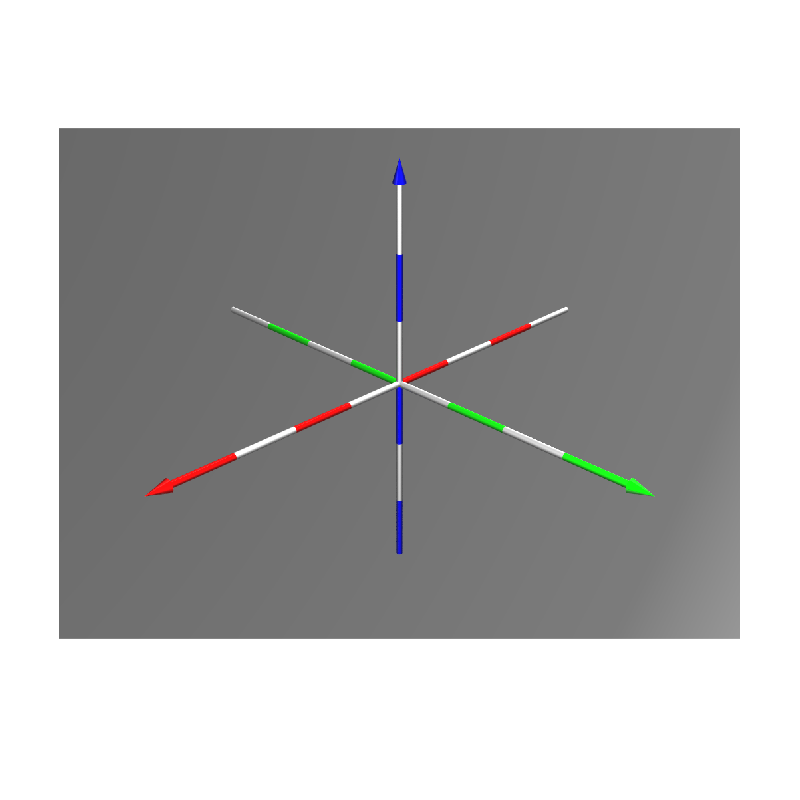

pl.scene_begin('scene_file', 'mesh.pov', 'image_file', 'mesh.png');
    pl.include("camera");
    pl.include("lights");
    pl.include("helpers");

    pl.axis('length', [4 4 3]);
pl.scene_end();

image = pl.render();
imshow(image);

#### **Custom colored thin axis**

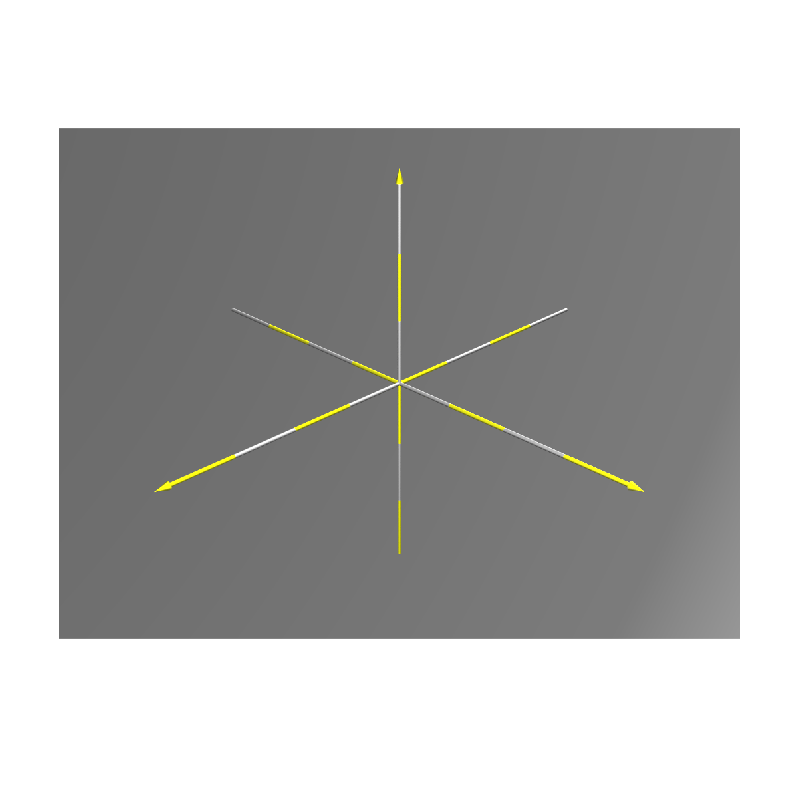


pl.scene_begin('scene_file', 'mesh.pov', 'image_file', 'mesh.png');
    pl.include("camera");
    pl.include("lights");
    pl.include("helpers");

    tex_axis_gray   = pl.declare("tex_axis_gray",   pl.texture('pigment', [0.5 0.5 0.5], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
    tex_axis_yellow = pl.declare("tex_axis_yellow", pl.texture('pigment', [1.0 1.0 0.0], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));

    pl.axis('length', [4 4 3], 'radius', 0.03, 'tex_common', tex_axis_gray, 'tex_x', tex_axis_yellow, 'tex_y', tex_axis_yellow, 'tex_z', tex_axis_yellow);
pl.scene_end();

image = pl.render();
imshow(image);

#### Display elapsed time

toc % Elapsed time

Elapsed time is 4.039314 seconds.
